Load audio files in MatLab

Fs = 44100;
range = [1,10*Fs];

bass = audioread("Samples\bass.wav",range);
guitar = audioread("Samples\guitar.wav", range);
drums = audioread("Samples\drums.wav", range);

Create a ramp effect for the drums

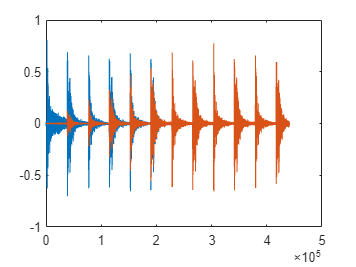

ramp = transpose(linspace(0,1,5*Fs));
N = length(ramp);

ramped_drums = drums;
ramped_drums(1:N) = ramped_drums(1:N).*ramp;

plot(drums)
hold on
plot(ramped_drums)
hold off

Make instruments stereo

guitar_stereo = [guitar*0.6, guitar*0.4];
bass_stereo = [bass*0.4,bass*0.6];
drum_stereo = [ramped_drums, ramped_drums];

Plot and Play the final result

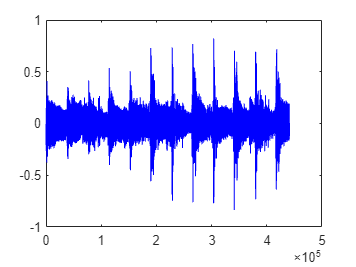

comp = drum_stereo + bass_stereo + guitar_stereo;
plot(comp, "b")

sound(comp,Fs)